a. The distribution that X follows is a Binomial Distribution.

The reasons are:

- There are a fixed number of trials (n = 1500 cars).

- Each trial is independent (the outcome of one car does not affect the outcome of another).

- There are only two possible outcomes: the brakes last at least 100000 miles or they do not.

- The probability of success (brakes not lasting 100000 miles) is the same for each trial (p = 0.02, since the company claims a 98% success rate).


$$$$ n = 1500, p = 0.02,$$$$


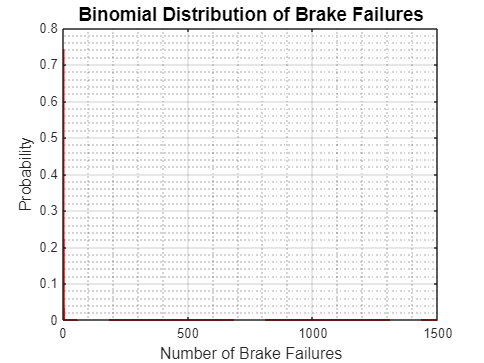

n = 1500; 
p = 0.0002;


x = 0:1:n;

y = binopdf(x, n, p);


figure;


bar(x, y, 'FaceColor', 'red', 'EdgeColor', 'red', 'LineWidth', 1.5);


title('Binomial Distribution of Brake Failures', 'FontSize', 14);
xlabel('Number of Brake Failures', 'FontSize', 12);
ylabel('Probability', 'FontSize', 12);

grid on; grid minor;

This code generates a bar graph of the binomial distribution of brake failures. The x-axis represents the number of brake failures, and the y-axis represents the probability of that number of failures occurring. The graph will likely show a peak at the expected value of failures (n*p = 1500 x *0.02 = 30), and then taper off on either side, reflecting the decreasing likelihood of a large deviation from the expected number of failures.

- Skewness: Skewness measures the asymmetry of a distribution. In this case, you would expect positive skewness, meaning the distribution has a longer right tail

- Kurtosis: Kurtosis measures the "tailedness" of a distribution.It has a low kurtosis, meaning the distribution has lighter tails and a flatter peak compared to a normal distribution. This is because the probability of a large number of failures is low, so there are fewer data points in the tails.

- Mode: The mode of a binomial distribution is typically around np, but can vary depending on the exact values of n and p. In this case, the mode would likely be close to the mean of 30.